# Present ... Arms

Adapted from Allen Downey's book [Probably Overthiking it](https://greenteapress.com/wp/probably-overthinking-it/), and the asociated [Jupyter notebooks](https://allendowney.github.io/ProbablyOverthinkingIt/intro.html).

## Download the data

Here's the ANSUR data, originally downloaded from [The OPEN Design Lab](https://www.openlab.psu.edu/ansur2).  Download it a local CSV file.

websave("ANSURIIFEMALEPublic.csv", ...
    "https://github.com/AllenDowney/ProbablyOverthinkingIt/raw/book/data/ANSURIIFEMALEPublic.csv");

websave("ANSURIIMALEPublic.csv", ...
    "https://github.com/AllenDowney/ProbablyOverthinkingIt/raw/book/data/ANSURIIMALEPublic.csv");

## Read and inspect the data

Read the data from the local file into a MATLAB [table](https://www.mathworks.com/help/matlab/tables.html) data type.

ansur_female = readtable("ANSURIIFEMALEPublic.csv");

ansur_male = readtable("ANSURIIMALEPublic.csv");

Look at the top few rows of each table

head(ansur_female)

    SubjectId    abdominalextensiondepthsitting    acromialheight    acromionradialelength    anklecircumference    axillaheight    balloffootcircumference    balloffootlength    biacromialbreadth    bicepscircumferenceflexed    bicristalbreadth    bideltoidbreadth    bimalleolarbreadth    bitragionchinarc    bitragionsubmandibulararc    bizygomaticbreadth    buttockcircumference    buttockdepth    buttockheight    buttockkneelength    buttockpopliteallength    calfcircumference    cervicaleheight    chestbreadth    chestcircumference    chestdepth    

head(ansur_male)

    subjectid    abdominalextensiondepthsitting    acromialheight    acromionradialelength    anklecircumference    axillaheight    balloffootcircumference    balloffootlength    biacromialbreadth    bicepscircumferenceflexed    bicristalbreadth    bideltoidbreadth    bimalleolarbreadth    bitragionchinarc    bitragionsubmandibulararc    bizygomaticbreadth    buttockcircumference    buttockdepth    buttockheight    buttockkneelength    buttockpopliteallength    calfcircumference    cervicaleheight    chestbreadth    chestcircumference    chestdepth    

[*The Measurer’s Handbook*](http://tools.openlab.psu.edu/publicData/ANSURII-TR11-017.pdf) used in the ANSUR survey is 253 pages, and includes details on "sampling strategy and measuring techniques" as well as descriptions and diagrams of the landmarks and measurements between them.

Since "stature" is defined as the heights in mm, convert to cm.

height_female = ansur_female.stature / 10;
height_male = ansur_male.stature / 10;

Plot

figure(1);
clf;

h = histogram(height_male, 'NumBins',40, 'Normalization','probability', 'DisplayStyle', 'bar','FaceAlpha', 0.4);
hold on;
h_female = histogram(height_female, 'NumBins',40, 'Normalization','probability', 'DisplayStyle', 'bar','FaceAlpha', 0.4);
ylabel('Fraction');
xlabel('Adult Height (cm)')
legend('Male','Female')

The following function plots a Gaussian curve with the same mean and std as the data.

The scale parameter is arbitrary -- I chose it to be roughly the same height as the histogram, which is also arbitrary. Avoiding this arbitrariness is one reason I prefer to use CDFs to compare the distribution of data with a model.

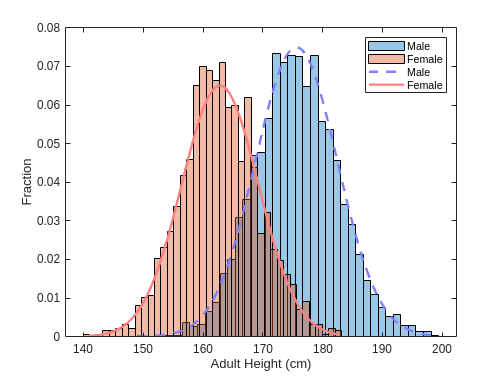

plot_normal_pdfs(height_male, 0.075, '--', [0.5 0.5 1], 'Male');
plot_normal_pdfs(height_female, 0.065, '-', [1 0.5 0.5], 'Female');

function plot_normal_pdfs(series, scale, lspec, color, label)
    mu = mean(series);
    sigma = std(series);
    qs = linspace(min(series), max(series), 100);
    ps = normpdf(qs, mu, sigma);
    ps = ps*scale / max(ps);
    plot(qs, ps, lspec, 'Color', color, 'DisplayName', label, 'LineWidth', 2)
end